# Fitting a Stepwise Linear Model

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

data = readtable("data\dataMulti.xlsx", Sheet="data");
dataTrain = readtable("data\dataMulti.xlsx", Sheet="dataTrain");
dataTest = readtable("data\dataMulti.xlsx", Sheet="dataTest");
whos data dataTrain dataTest

  Name             Size            Bytes  Class    Attributes

  data           100x4              4813  table              
  dataTest        30x4              2573  table              
  dataTrain       70x4              3853  table              



## Tasks 1 & 3

The table `data` has been split into a training set, `dataTrain`, and a test set, `dataTest`.

To fit a stepwise linear regression model, you can use the `stepwiselm` function.

`lnMdl` `=` `stepwiselm``(``table``)`

You can use the `predict` function to predict the response on your test data.

`predictions` `=` `predict``(``lnMdl``,``testData``)`

Starting with a different model may yield a different formula. You can specify the initial model by using a second input.

`lnMdl` `=` `stepwiselm``(``table``,``"``modelspec``"``)`

mdl = stepwiselm(dataTrain, "purequadratic");

1. Removing X2^2, FStat = 0.84426, pValue = 0.36192
2. Removing X2, FStat = 0.59788, pValue = 0.44243


yPred = predict(mdl, dataTest);

## Task 2

You can use dot indexing to examine properties of the model, such as the model formula or the root mean squared error (RMSE).

`lnMdl.Formula`

`lnMdl.RMSE`

formula = mdl.Formula

formula = Y ~ 1 + X1 + X3 + X1^2 + X3^2

Compare predicted and actual responses.

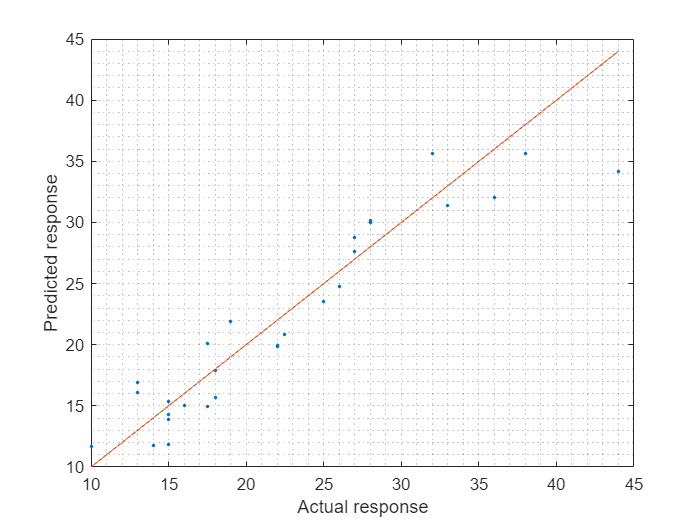

plot(dataTest.Y, yPred, ".")
hold on
plot(dataTest.Y, dataTest.Y)
hold off
grid minor
xlabel("Actual response")
ylabel("Predicted response")